# Lab 3. 

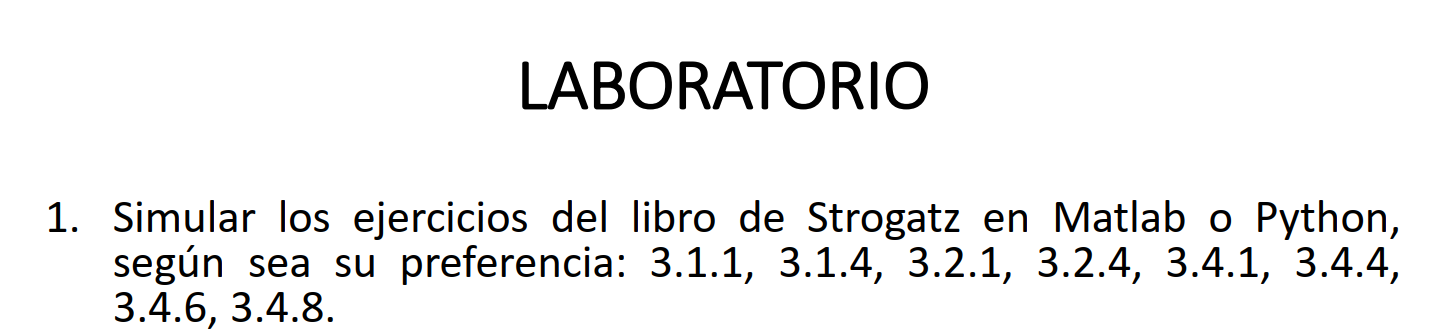

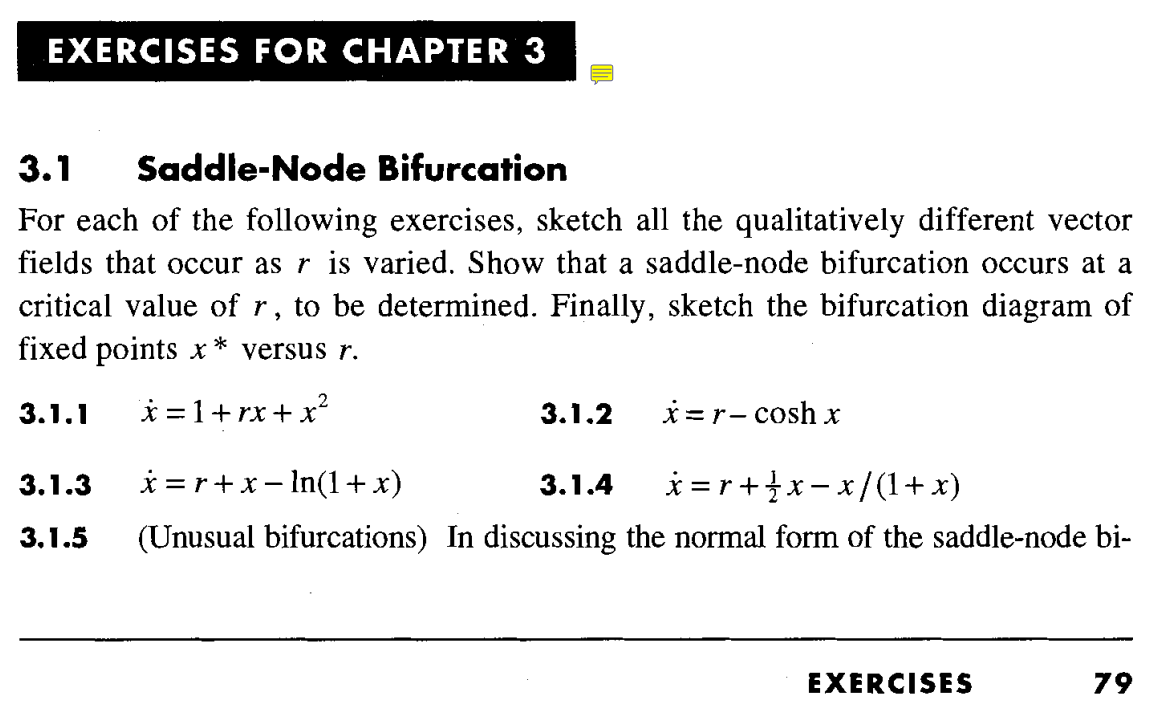

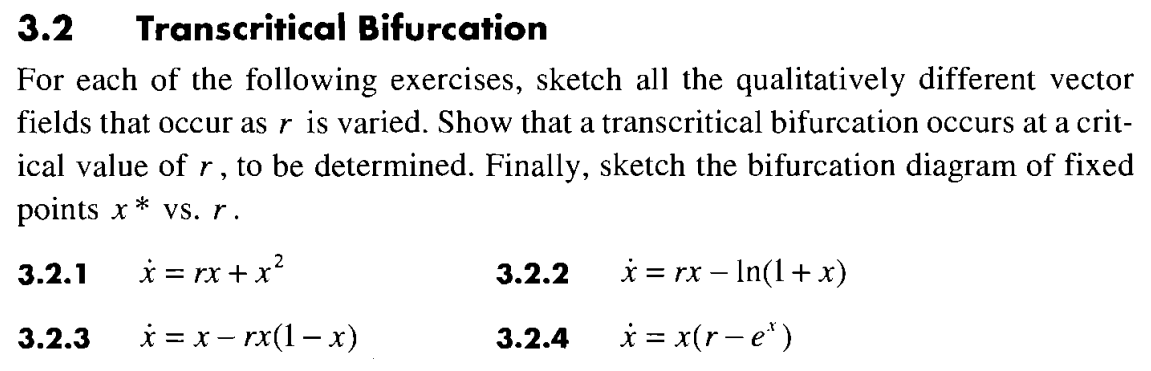

## 3.2.1

# Bifurcaciones en sistemas unidimensionales

clc;clear;close all

## Bifurcación Saddle-Node

Para este tipo de bifurcación, se analiza el siguiente sistema:


$$\dot{x} =\mathrm{rx}+x^2$$


Donde $r$ es el parámetro de bifurcación

disp("Ejercicio 3.2.1")

Ejercicio 3.2.1


syms x r
Fsn =r*x+x^2

$$Fsn = x^{2}+r\,x$$

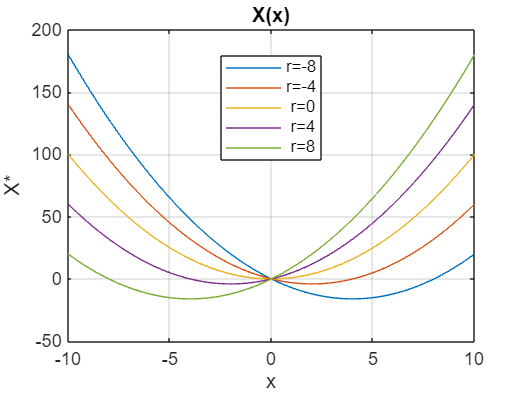


% GRAFICA X(x) con variantes de r:
r_desde=-8; r_hasta=8; r_paso=4;
r_grafica=r_desde:r_paso:r_hasta; %Asigno valor.
x_desde=-10; x_hasta=10;
x_grafica=linspace(x_desde,x_hasta,100);
for i = 1:length(r_grafica)
    Fsn_grafica=real(subs(subs(Fsn,r,r_grafica(i)),x,x_grafica)); %sustituye r y x por valor numéricos.
    plot(x_grafica,Fsn_grafica); %Grafica Fsn con variantes de r.
    hold on;
end
%ylim([-15 15])
grid on
title("X(x)");
xlabel("x");
ylabel("X*");
% Crear leyenda para indicar valores de r
legendStrings = cellstr(num2str(r_grafica', 'r=%g'));
legend(legendStrings, 'Location', 'best');
hold off;

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100) %resuelve eca, despeja X y simplifica hasta 100 pásos.

$$xss\_sn = \left(\begin{array}{c} 0\\ -r \end{array}\right)$$

En este caso, tenemos 2 PE. Por lo que se linealiza en estos puntos

A = jacobian(Fsn,x); %Linealiza.

A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1

$$A\_a = r$$

A_b = subs(A,x,xss_sn(2)) % Para PE 2.

$$A\_b = -r$$


r_asignado=4 %Asignamos valor para probar.

r_asignado = 4

disp("Si el resultado del jacobiano da negativo, el polo es estable, 0 es medio estable: ")

Si el resultado del jacobiano da negativo, el polo es estable, 0 es medio estable: 


reemplaza_r_asignado_A_a=subs(A_a,r,r_asignado)

$$reemplaza\_r\_asignado\_A\_a = 4$$

reemplaza_r_asignado_A_b=subs(A_b,r,r_asignado)

$$reemplaza\_r\_asignado\_A\_b = -4$$

En este caso, para los dos PE se hace el siguiente análisis:

- 
$$x_a =0$$


Con el  jacobiano $A=r$, para que este polo sea estable$\;r<0$ 

- 
$$x_b =-r$$


Con el  jacobiano $A=-r$, para que este polo sea estable$\;r>0$ 

xss_sn_num = double(subs(xss_sn,r,r_asignado))

xss_sn_num =      0
    -4


disp("Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t")

Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t


## Simulación de la Bifurcación Saddle - Node

Tsim = 40;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = -3;                 % Condiciones iniciales Modificarse ++++++++++++++
disp("Condición inicial: "+ x0);

Condición inicial: -3


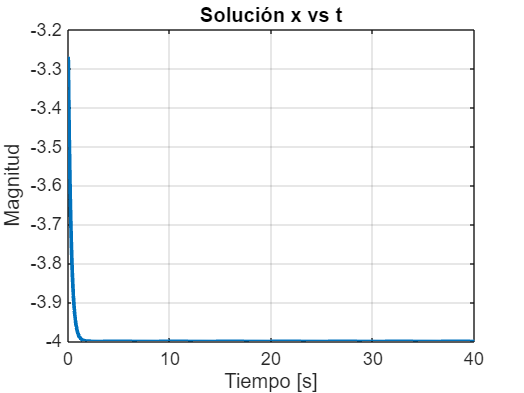

Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(-10,10,Ns); % Debe modificarse+++++++++++++++++++++++
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode(t,x,r_asignado), [0 Ts], x0); %REVISAR SI DEBE PONERSE R ASIGNADO +++++++++++++++++++
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

%subplot(1,2,1)
plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on

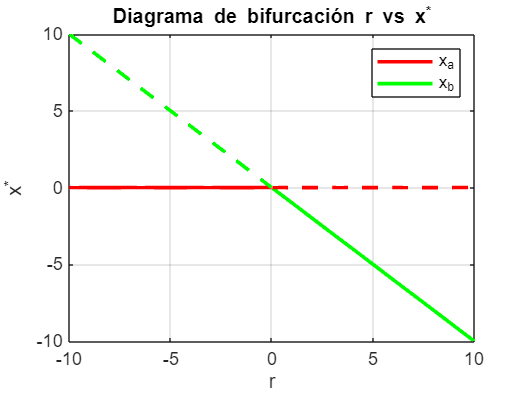

%subplot(1,2,2)
plot(r_sim(r_sim <= 0), real(fr(1, r_sim <= 0)), 'LineWidth', 2, 'Color', 'r');
hold on
plot(r_sim(r_sim >= 0), real(fr(2, r_sim >= 0)), 'LineWidth', 2, 'Color', 'g');
plot(r_sim(r_sim >= 0), real(fr(1, r_sim >= 0)), 'LineWidth', 2, 'Color', 'r', 'LineStyle', '--'); 
plot(r_sim(r_sim <= 0), real(fr(2, r_sim <= 0)), 'LineWidth', 2, 'Color', 'g', 'LineStyle', '--');
hold off
legend(["x_a" "x_b"]);
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
grid on

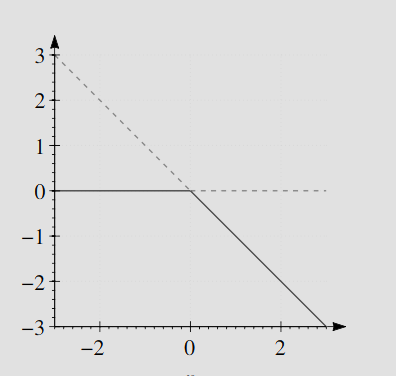

Los valores que aparecen entre -2 y +2 no deben ser tenidos en cuenta, ya que estos valores cuentan con parte imaginaria y por ahora, eso no tiene sentido

#### Bifurcación Saddle - Node

function dxdt = saddlenode(t,x,r)
    dxdt = r*x+x^2;
end